simtime = 25

simtime = 25

A = 0

A = 0

W = tf(2, [3 A 12])

W =
 
      2
  ----------
  3 s^2 + 12
 
Continuous-time transfer function.



% АЧХ
syms w

Wjw = ( 2 ) / ( 3*(j*w)^2 + A*j*w + 12)

$$Wjw = -\frac{2}{3\,w^{2}-12}$$

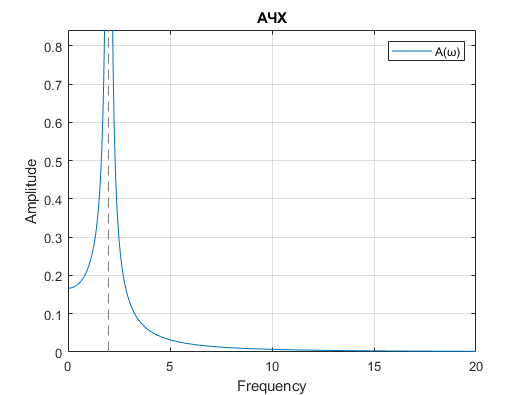

A1=sqrt(real(Wjw)^2+imag(Wjw)^2);

fplot(A1,[0,20])
grid on
xlabel("Frequency")
ylabel("Amplitude")
title("АЧХ")
legend("A(ω)")

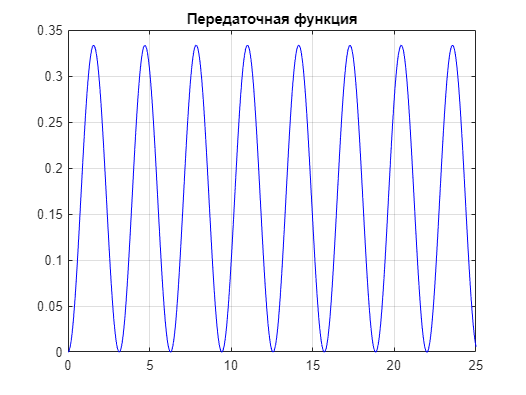

first = sim("test.slx", simtime);
plot(first.simout.Time, first.simout.Data, 'blue')
grid on
title("Передаточная функция")

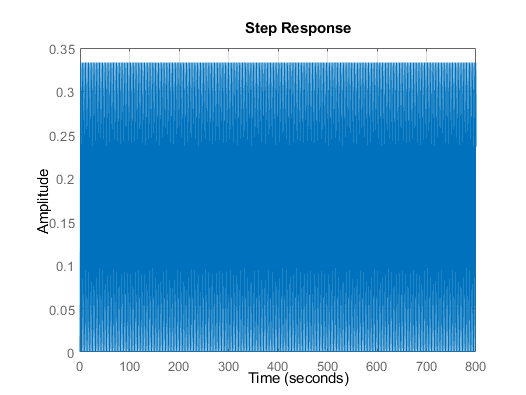

step(W)
grid on